df = readtable('data.csv');
data = df(:,[1,10,12,13,14,21])

data = 2000×6 table
    battery_power    n_cores    px_height    px_width    ram     price_range
    _____________    _______    _________    ________    ____    ___________

         842            2           20          756      2549         1     
        1021            3          905         1988      2631         2     
         563            5         1263         1716      2603         2     
         615            6         1216         1786      2769         2     
        1821            2         1208         1212      1411         1     
        1859            1         1004         1654      1067         1     
        1821            8          381         1018      3220         3     
        1954            4          512         1149       700         0     
     


cleaned_data = rmmissing(data)

cleaned_data = 2000×6 table
    battery_power    n_cores    px_height    px_width    ram     price_range
    _____________    _______    _________    ________    ____    ___________

         842            2           20          756      2549         1     
        1021            3          905         1988      2631         2     
         563            5         1263         1716      2603         2     
         615            6         1216         1786      2769         2     
        1821            2         1208         1212      1411         1     
        1859            1         1004         1654      1067         1     
        1821            8          381         1018      3220         3     
        1954            4          512         1149       700         0   

tmp = cvpartition(cleaned_data.price_range,'HoldOut',0.30);
train_idx = training(tmp);
test_idx = test(tmp);

training_data = cleaned_data(train_idx,:)

training_data = 1400×6 table
    battery_power    n_cores    px_height    px_width    ram     price_range
    _____________    _______    _________    ________    ____    ___________

         842            2           20          756      2549         1     
        1021            3          905         1988      2631         2     
         563            5         1263         1716      2603         2     
         615            6         1216         1786      2769         2     
        1821            2         1208         1212      1411         1     
        1859            1         1004         1654      1067         1     
        1821            8          381         1018      3220         3     
        1954            4          512         1149       700         0  

testing_data = cleaned_data(test_idx,:)

testing_data = 600×6 table
    battery_power    n_cores    px_height    px_width    ram     price_range
    _____________    _______    _________    ________    ____    ___________

         509            5         1137         1224       513         0     
        1520            8          151         1005      3826         3     
        1866            1          356          563       373         0     
         838            8          984         1850      3554         3     
         595            3          441          810      3752         3     
        1709            2          974         1385      3283         3     
        1949            4          407          822      1433         1     
        1602            3          466          788      1037         0    

x_training = training_data(:,[1,2,3,4,5]);
y_training = training_data(:,[6]);

x_testing = testing_data(:,[1,2,3,4,5]);
y_testing = testing_data(:,[6]);

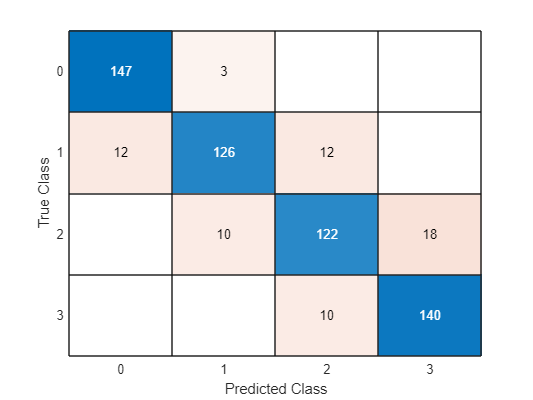

model = fitcknn(x_training,y_training);
pdc = predict(model,x_testing);

confusionmatrix = confusionchart(table2array(y_testing),pdc);


confusionmatrix_model = confusionmat(table2array(y_testing),pdc)

confusionmatrix_model =    147     3     0     0
    12   126    12     0
     0    10   122    18
     0     0    10   140


accuracy = sum(diag(confusionmatrix_model))/sum(confusionmatrix_model(:))*100

accuracy = 89.1667